data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

load_img = strcat(data_root_dir, movie_root_dir, current_movie);

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

imread(load_img);

## Total Number of Conditions

pepANA.no_conditions

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{13}

## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

(size(pepANA.listOfResults{1}.repeat{1}.data{1}{1}, 2) / 30000) * 1000

## Electrodes

pepANA.elec_list

## Examining Waveforms

q = pepANA.listOfResults{1}.repeat{1}.data{13}{2};
% size(q(1, :));
% one_waveform = q(1, :);
% plot(one_waveform)

% fig_multiple_spikes_electrode13 = figure("Name", "Channel 13 Electrode");
% ax_multi_spikes_channel13 = axes("Parent", fig_multiple_spikes_electrode13);
% plot(ax_multi_spikes_channel13, q);

## SVD of Waveforms

function mean_detected_signal = analyzeWaveform(condition, electrode, verbose)
    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    if nargin < 3
        verbose = false;
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveform
    waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveform is in double precision
    waveform = double(waveform);

    % Perform SVD
    [~, ~, v] = svd(waveform);

    % Plot first two principal components
    if verbose
        fig1 = figure('Name', 'Original Waveforms', 'Position', [100, 100, 800, 600]);
        ax1 = axes('Parent', fig1);
        plot(ax1, v(:, 1), v(:, 2), '.', 'MarkerSize', 10);
        hold(ax1, 'on');
        plot(ax1, 0, 0, 'r.', 'MarkerSize', 25);
        xlabel(ax1, '1st Principal Component');
        ylabel(ax1, '2nd Principal Component');
        title(ax1, sprintf('SVD Projection: Condition %d, Electrode %d', condition, electrode));
        grid(ax1, 'on');
    end
        

    idx = kmeans(double(waveform'),2); %% cluster waveforms in 2 classes using k-means
    idx1 = find(idx==1); 
    idx2 = find(idx==2);

    % Determine which cluster is likely the signal
    mean1 = mean(waveform(:, idx1), 2);
    mean2 = mean(waveform(:, idx2), 2);

    total_amplitude1 = sum(abs(mean1));
    total_amplitude2 = sum(abs(mean2));

    if total_amplitude1 > total_amplitude2
        signal_idx = idx1;
        noise_idx = idx2;
    else
        signal_idx = idx2;
        noise_idx = idx1;
    end

    if verbose
        fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
        ax3_1 = subplot(1, 2, 1, "Parent", fig2);
        plot(ax3_1, v(noise_idx, 1), v(noise_idx, 2), 'b.', 'markersize',10); 
        hold on;
        plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
        plot(ax3_1, v(signal_idx, 1), v(signal_idx, 2), 'g.', 'markersize', 10);
    
        ax3_2 = subplot(1, 2, 2, "Parent", fig2);
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, signal_idx)'),1), std(double(waveform(:, signal_idx)'),[],1), 'g'); 
        hold on;
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, noise_idx)'),1), std(double(waveform(:, noise_idx)'),[],1), 'b');
    
        xlim([0 49])
    end
    mean_detected_signal = mean(double(waveform(:, signal_idx)'),1);
end

data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

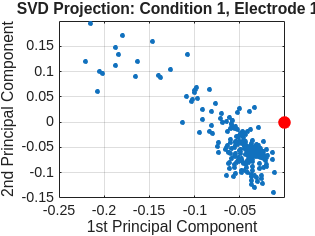

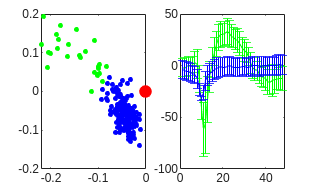

signal =    -1.5556   -2.3704   -1.0741   -0.0741   -0.4074    0.9630    3.4444    1.3333  -13.0370  -41.1111  -61.7037  -54.7778  -32.4815  -10.9630    3.4074   13.7037   20.7778   27.2963   30.4815   29.7037   31.1481   32.7778   30.8148   28.7037   27.3333   25.5926   24.4444   21.4444   16.9259   14.7778   12.9630    8.5926    2.7407   -1.5185   -3.3333   -5.1481   -8.5556  -10.8889  -11.0000  -12.2222  -15.6667  -15.9630  -14.5556  -13.3333  -13.1481  -12.5926  -11.9630  -12.2593


signal = analyzeWaveform(1, 13, true)

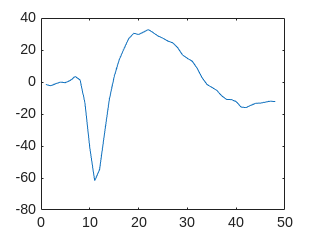

fig0 = figure('Name', 'Detected Waveform', 'Position', [100, 100, 800, 600]);
ax0 = axes('Parent', fig0);
plot(ax0, signal)



waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

[u, s, v] = svd(double(q));
fig1 = figure('Name', 'Original Waveforms', "Position", [100, 100, 800, 600]);
ax1 = axes("Parent", fig1);
plot(ax1, v(:, 1), v(:, 2), '.', 'markersize', 10);
hold on;
plot(ax1, 0,0, 'r.', 'markersize', 25);

## Classifying Waveforms with K-means clustering

fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");

idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
idx1 = find(idx==1); 
idx2 = find(idx==2);

ax3_1 = subplot(1, 2, 1, "Parent", fig2);
plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
hold on;
plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);

ax3_2 = subplot(1, 2, 2, "Parent", fig2)
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); 
hold on;
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');

xlim([0 49])

% set(gcf, 'Renderer', 'painters'); % or 'opengl'

% waveform = pepANA.listOfResults{1}.repeat{1}.data{13}{2}(1, :)
% fig0 = figure("Name", "Single Waveform");
% ax0 = axes("Parent", fig0);
% plot(ax0, waveform);

% plot(ax0, pepANA.listOfResults{1}.repeat{1}.data{13}{1})

## Natural image sequences data:

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);
frame_idx

frame_idx(1);
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1)

## Getting the frames

movie_id = pepANA.listOfResults{120}.values(1);
segment_id = pepANA.listOfResults{120}.values(2);

n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1)
prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);

% Create the string to show the image that is the stimulus to the detected spike
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1);
prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros))
movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx(1)) + ".jpeg"
movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/"
image_path = strcat(movie_image_dir, movie_image_string);
img = imread(image_path);
imshow(img)